# Analyze Battery Impedance Using Exact Linearization

This example shows how to measure the impedance of a battery designed using Simscape™ Battery™ software. You can use impedance analysis to measure the performance and characteristics of a battery. For a battery modeled using the [Battery Equivalent Circuit](https://www.mathworks.com/help/simscape-battery/ref/batteryequivalentcircuit.html) block, you can analyze the impedance using the linearization tools from Simulink® Control Design™ software. In this example, you linearize the model at 100% state of charge (SOC) and compare the linearization results with the transfer function that you manually derive from the equivalent circuit model. This example also shows how to use batch linearization to linearize the model at different SOC levels.

## Examine Model

The example model uses a Battery Equivalent Circuit block and discharges from different SOC levels at a constant current value.

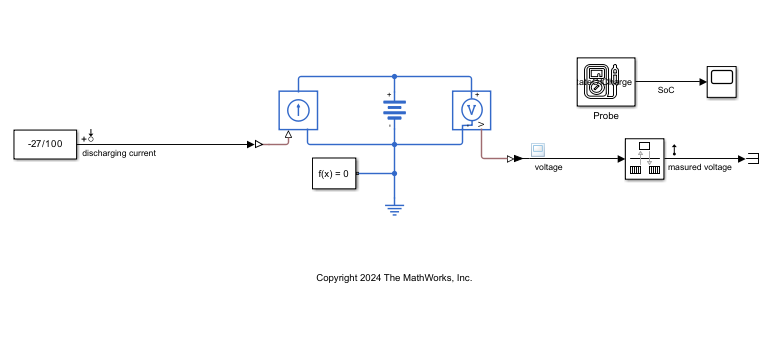

## Linearize Model and Compare with Derived Transfer Function

To obtain a linear model of the Battery Equivalent Circuit block, you can use the [`linearize`](https://www.mathworks.com/help/slcontrol/ug/linearize.html) command. This example provides a Simulink model with preconfigured linear analysis points.

Open the model.

mdl_linearize = "BatteryImpedanceLinearize";
open_system(mdl_linearize);

Linearize the model at the default SOC value of 100% defined in the variable `soc_ini`.

io = getlinio(mdl_linearize);
linsys_soc100 = linearize(mdl_linearize,io,0.5);

For this model, the parameter values of the Battery Equivalent Circuit block describe the circuit in this image. 

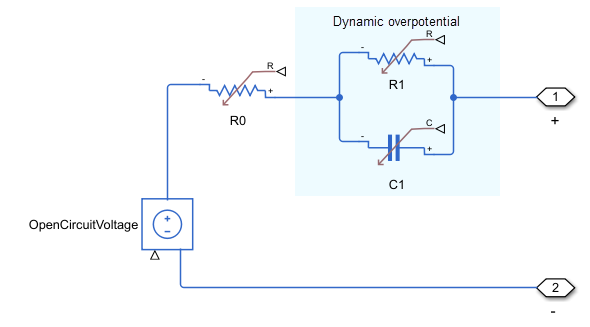

The Simulink model has one time constant that corresponds to the resistor-capacitor pair represented in the image by the `R1` and `C1` blocks. Based on the circuit diagram, this transfer function describes the impedance:

$Z=R_0 +\frac{R_1 }{\tau_1 s+1}$.

At an SOC level of 100%, you can manually derive the transfer function using the values defined in the block parameters.

R0 = 0.0085;
R1 = 0.017;
Tau1 = 0.39;
Z_soc100 = tf([Tau1*R0 R0+R1],[Tau1 1]);

Compare the impedance results obtained from linearization and your manual derivation.

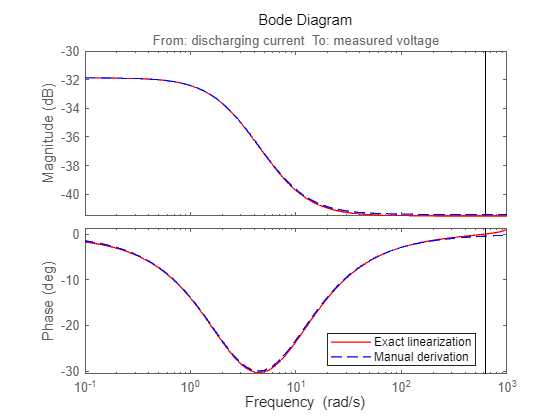

figure;
w = logspace(-1,3,100);
bode(linsys_soc100,w,"r",Z_soc100,"b--");
legend("Exact linearization","Manual derivation",Location="best");

You can also compare the Nyquist response of the two models using the `nyquist` command.

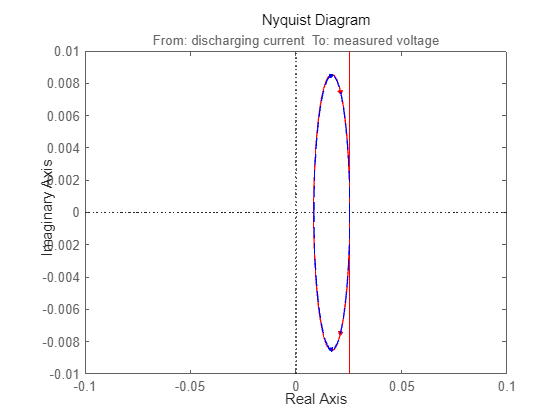

nyquist(linsys_soc100,"r",Z_soc100,"b--")
axis([-0.1 0.1 -0.01 0.01])

## Use Batch Linearization to Compare Different Levels of SOC

Using batch linearization, you can linearize the model at different SOC levels and compare the results. Define five SOC values from 20% to 100%.

soc_grid = 0.2:0.2:1;

Use the `soc_ini` variable to vary the SOC value and perform the batch linearization.

params(1).Name = "soc_ini";
params(1).Value = soc_grid;
lin_sys_soc = linearize(mdl_linearize,io,0.5,params);

The batch linearization result is an array of state-space models that correspond to the SOC values.

Plot the batch linearization results.

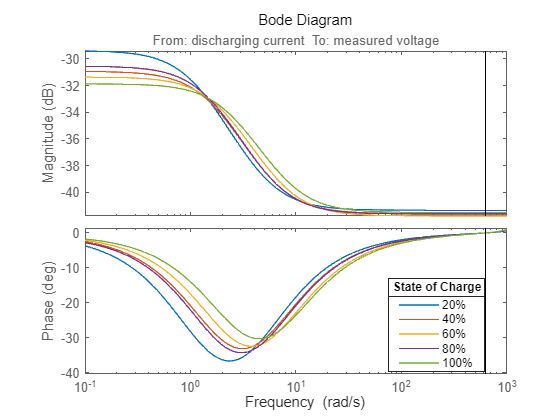

figure;
bode(lin_sys_soc(:,:,1,1),lin_sys_soc(:,:,2,1),...
    lin_sys_soc(:,:,3,1),lin_sys_soc(:,:,4,1),...
    lin_sys_soc(:,:,5,1),w);
ldg = legend("20%","40%","60%","80%","100%",Location="best");
title(ldg,"State of Charge")

## Create LPV Model for Battery Cell Models

A *linear parameter-varying* (LPV) system is a linear state-space model whose dynamics vary as a function of certain time-varying parameters called *scheduling parameters*. In MATLAB®, an LPV model is represented in a state-space form using coefficients that are parameter dependent. Using the batch linearization result, you can build a gridded LPV model that depends on the parameter of SOC.

lpv_sys_soc = ssInterpolant(lin_sys_soc,'spline');

Having an LPV model makes it much easier to analyze the battery cell's behavior because of its reduced model complexity. For example, you can use a much finer grid of SOC values to resample the LPV model. Compared to the 20% step used in batch linearization, you can use 5% as a new step value in an array of time-invariant state-space model.

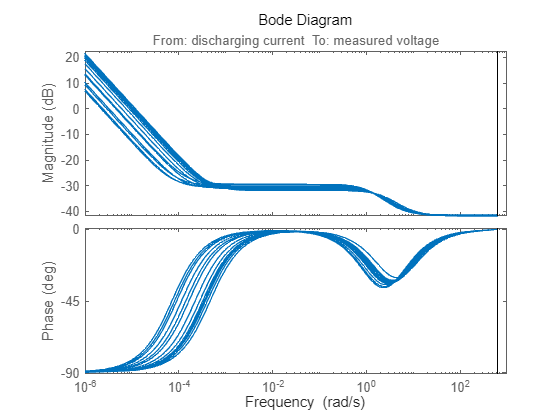

soc_fine_grid = 0.2:0.05:1;
ssArray = psample(lpv_sys_soc,[],soc_fine_grid);
figure; 
bode(ssArray);

While capturing behaviors at different SOC levels, this plant model greatly reduces battery cell model's complexity for further analysis.

*Copyright 2024 The MathWorks, Inc.*